## Detecting Features

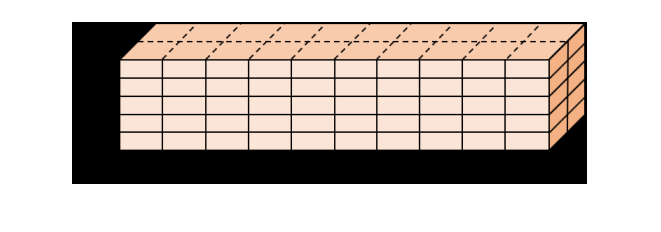

building = imread("building.png");
imshow(building)

buildingBW = im2gray(building);
corners = detectHarrisFeatures(buildingBW)

corners =   229×1 cornerPoints 配列のプロパティ:

    Location: [229×2 single]
      Metric: [229×1 single]
       Count: 229


corners.Location

ans = 229×2 の single 行列
   49.9466   39.8222
   49.8307   56.7500
   49.8018   75.3706
   49.8287   93.0190
   49.8307  110.7500
   49.9081  127.0919
   51.4504   37.2353
   69.9844   19.0654
   77.0452   20.0681
   80.8820   20.0744


corners.Metric

ans = 229×1 の single 列ベクトル
    0.0243
    0.0315
    0.0366
    0.0354
    0.0315
    0.0282
    0.0206
    0.0292
    0.0133
    0.0138


corners.Count

ans = 229

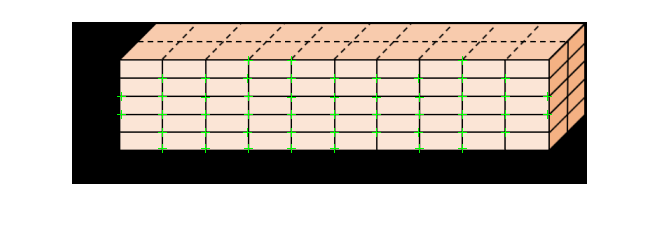

imshow(building)
strongestCorners = selectStrongest(corners,50);
hold on
% plot(corners)
plot(strongestCorners)
hold off

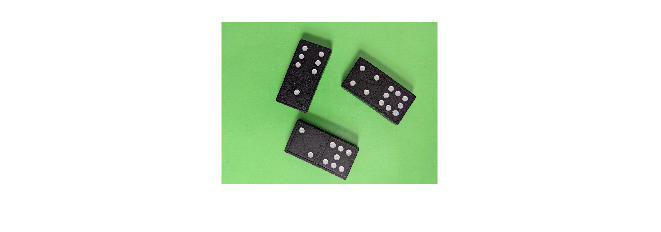

dominos = imread("dominos.jpg");
imshow(dominos)

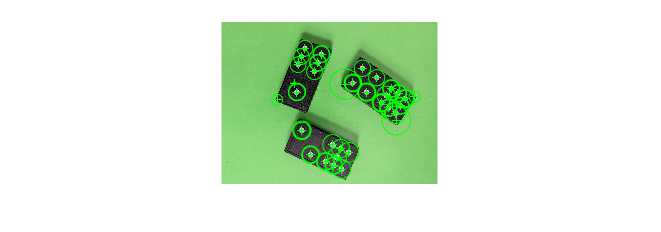

dominosBW = im2gray(dominos);
% points = detectSURFFeatures(dominosBW);
points = detectSURFFeatures(dominosBW,"NumOctaves",5);
strongestPoints = selectStrongest(points, 50);
imshow(dominos);
hold on;
plot(strongestPoints);
hold off;

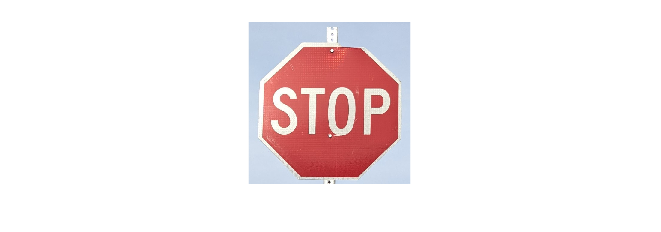

stop = imread("stopSign.jpg");
imshow(stop)

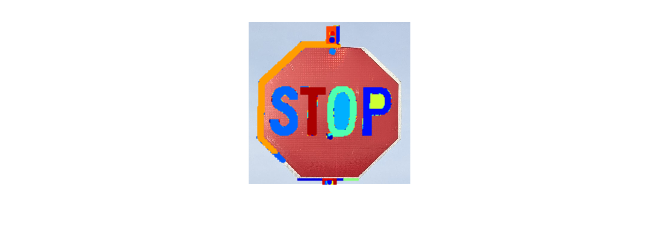

stopBW = im2gray(stop);
regions = detectMSERFeatures(stopBW);
imshow(stop);
hold on;
plot(regions, "showPixelList",true,"showEllipses",false);
hold off;

## Refining Feature Detection

clear
clc

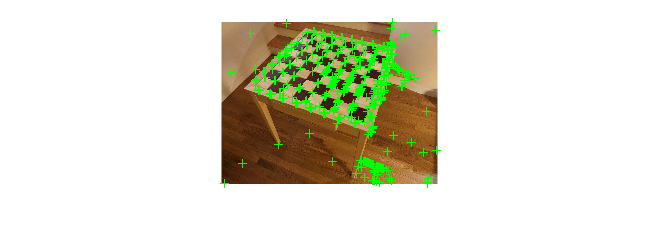

chesstableRGB = imread("chesstable.jpg");
chesstable = im2gray(chesstableRGB);
corners = detectHarrisFeatures(chesstable);
imshow(chesstableRGB);
hold on;
plot(corners);
hold off;

numCorner = height(corners);

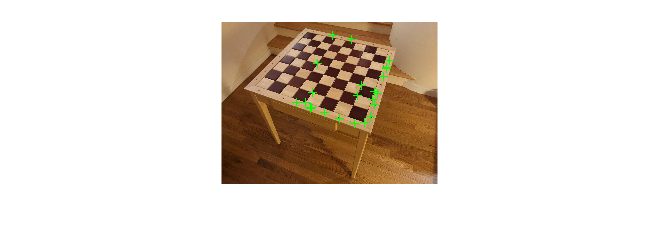

imshow(chesstableRGB);
hold on
plot(selectStrongest(corners,26))

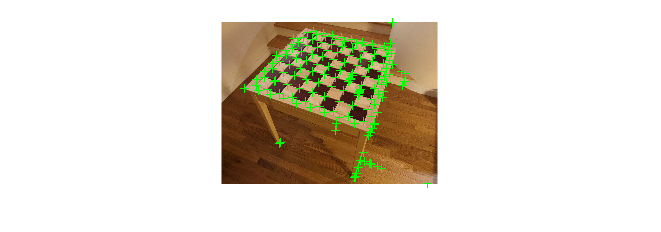

chessCorners = detectHarrisFeatures(chesstable,"FilterSize",49);
imshow(chesstableRGB)
hold on;
plot(chessCorners);
hold off;

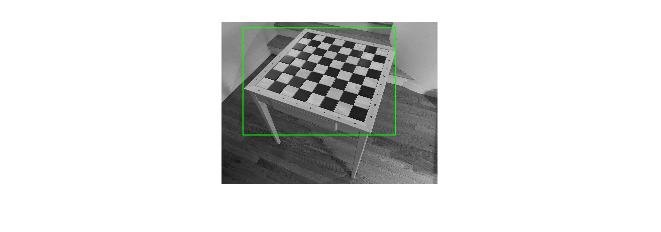

chesstableROI = [400,110,2850,2000];
imshow(chesstable)
rectangle("Position",chesstableROI,"EdgeColor","g")

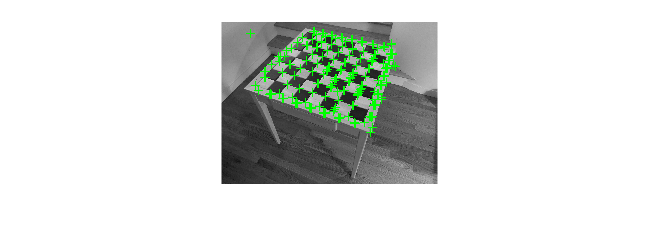

cornersROI = detectHarrisFeatures(chesstable,"ROI",chesstableROI);
numCorner = height(cornersROI);
imshow(chesstable);
hold on;
plot(selectStrongest(cornersROI,324));
hold off;

dominos = imread("dominos.jpg");
dominosBW = im2gray(dominos);
points = detectSURFFeatures(dominosBW,"NumOctaves",5)

points =   1918×1 SURFPoints 配列のプロパティ:

              Scale: [1918×1 single]
    SignOfLaplacian: [1918×1 int8]
        Orientation: [1918×1 single]
           Location: [1918×2 single]
             Metric: [1918×1 single]
              Count: 1918


[features, validPoints] = extractFeatures(dominosBW,points)

features = 1918×64 の single 行列
   -0.0002   -0.0006    0.0009    0.0011   -0.0020   -0.0030    0.0056    0.0061   -0.0024   -0.0011    0.0086    0.0061    0.0142   -0.0008    0.0142    0.0008    0.0003    0.0006    0.0038    0.0051    0.2110    0.2139    0.2578    0.2448   -0.2294    0.2203    0.2507    0.2472    0.0880   -0.0040    0.0880    0.0048    0.0016   -0.0001    0.0043    0.0028    0.2385   -0.1960    0.2615    0.2821   -0.2527   -0.1689    0.2818    0.3121    0.0722   -0.0053    0.0722    0.0054   -0.0000   -0.0003
    0.0003    0.0003    0.0006    0.0004    0.0489   -0.0426    0.0524    0.0579   -0.0498   -0.0376    0.0521    0.0526    0.0092   -0.0000    0.0092    0.0002   -0.0015   -0.0010    0.0038    0.0033    0.2405    0.2000    0.2748    0.2706   -0.2477    0.1948    0.2853    0.2514    0.0712    0.0008    0.0712    0.0022   -0.0016    0.0011    0.0046    0.0048    0.2159   -0.2115    0.2522    0.2551   -0.2291   -0.2172    0.2784    0.2671    0.0724    0.0007    0.07

validPoints =   1918×1 SURFPoints 配列のプロパティ:

              Scale: [1918×1 single]
    SignOfLaplacian: [1918×1 int8]
        Orientation: [1918×1 single]
           Location: [1918×2 single]
             Metric: [1918×1 single]
              Count: 1918


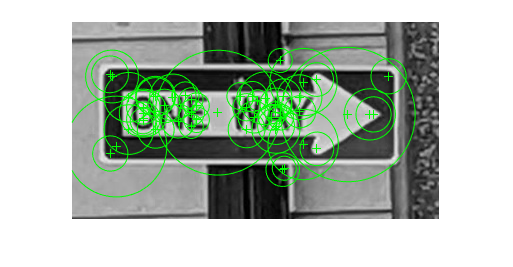

I1 = imread("oneway1.png");
I2 = imread("oneway2.png");

points1 = detectSURFFeatures(I1);
points2 = detectSURFFeatures(I2);

points1 = selectStrongest(points1,50);
points2 = selectStrongest(points2,50);

imshow(I1)
hold on;
plot(points1)
hold off

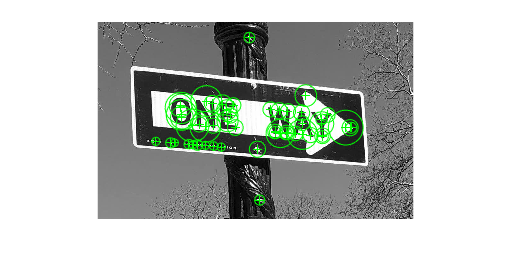


imshow(I2)
hold on
plot(points2)
hold off

clf

[features1,validPoints1] = extractFeatures(I1,points1);
[features2,validPoints2] = extractFeatures(I2,points2);

indexPairs = matchFeatures(features1,features2)

indexPairs = 6×2 の uint32 行列
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5


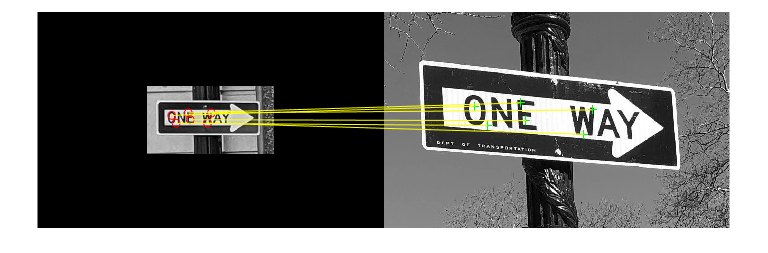


matchPoints1 = validPoints1(indexPairs(:,1));
matchPoints2 = validPoints2(indexPairs(:,2));

% showMatchedFeatures(I1,I2,matchPoints1,matchPoints2)
showMatchedFeatures(I1,I2,matchPoints1,matchPoints2,"montage")

## Matching Features

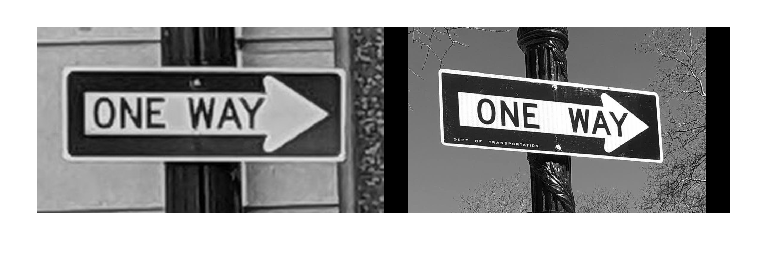

ow1 = imread("oneway1.png");
ow1 = im2gray(ow1);
ow2 = imread("oneway2.png");
ow2 = im2gray(ow2);
montage({ow1,ow2})

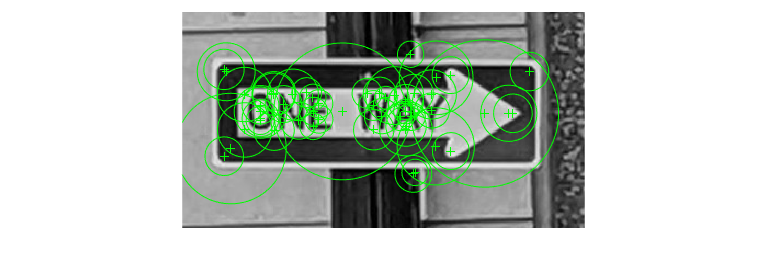


points1 = detectSURFFeatures(ow1);
points2 = detectSURFFeatures(ow2);

nKeep = 50;
points1 = selectStrongest(points1,nKeep);
points2 = selectStrongest(points2,nKeep);

imshow(ow1)
hold on
plot(points1)
hold off

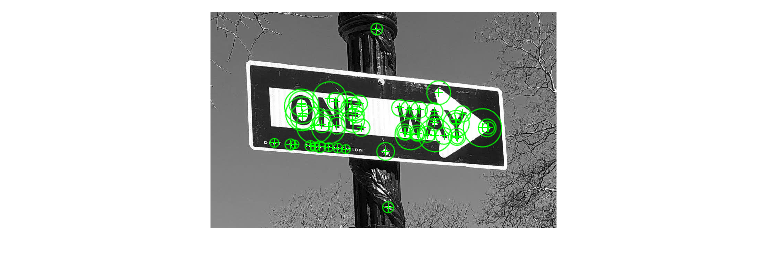


imshow(ow2)
hold on
plot(points2)
hold off

clf

[features1,validPoints1] = extractFeatures(ow1,points1);
[features2,validPoints2] = extractFeatures(ow2,points2);

indexPairs = matchFeatures(features1,features2)

indexPairs = 6×2 の uint32 行列
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5



matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2));

showMatchedFeatures(ow1,ow2,matchPoints1,matchPoints2,"montage")

indexPairs = matchFeatures(features1,features2,"MatchThreshold",100)

indexPairs = 8×2 の uint32 行列
    8    3
    9   40
   10   20
   16   47
   25   43
   28   14
   29   36
   42    5


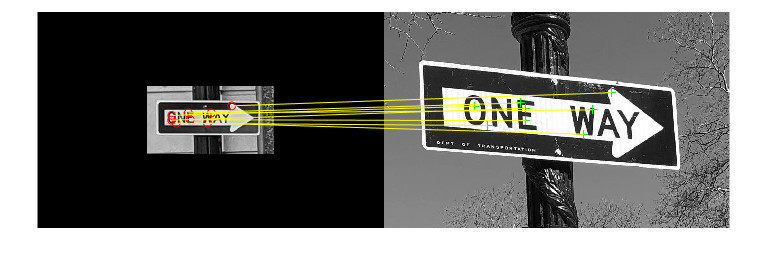


matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2));

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")

indexPairs = matchFeatures(features1,features2,"MatchThreshold",2,...
    "MaxRatio",1)

indexPairs = 19×2 の uint32 行列
    8    3
    9   40
   10   20
   15   39
   16   47
   17   32
   19   39
   20   50
   25   43
   26   36


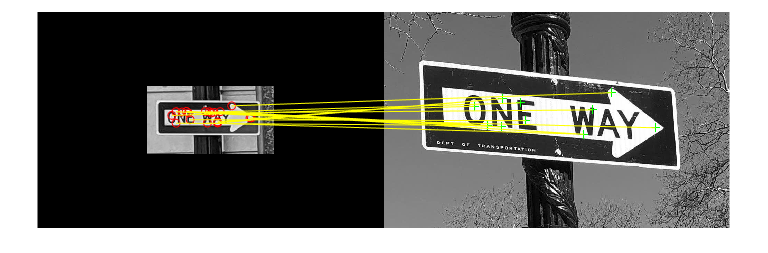

matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2));
showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")

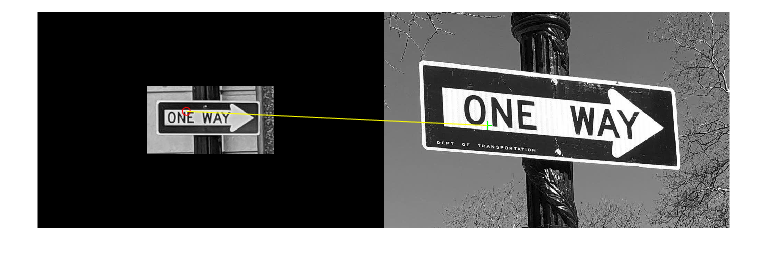

nMatches = height(matchedPoints1);
idx = 10;
showMatchedFeatures(ow1,ow2,matchedPoints1(idx),matchedPoints2(idx),"montage");

indexPairs = matchFeatures(features1,features2,"MatchThreshold",2, ...
    "MaxRatio", 1, ...
    "Unique",true)

indexPairs = 9×2 の uint32 行列
    8    3
    9   40
   10   20
   15   39
   16   47
   25   43
   29   36
   35   32
   42    5


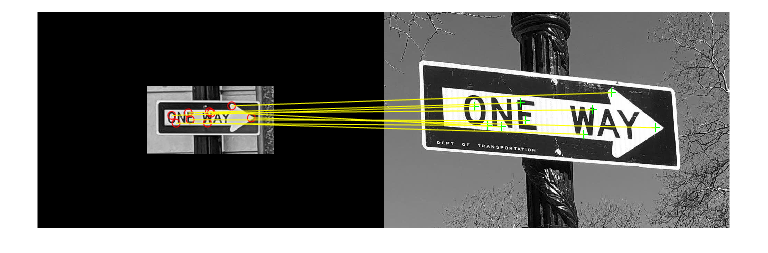

matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2));
showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage");

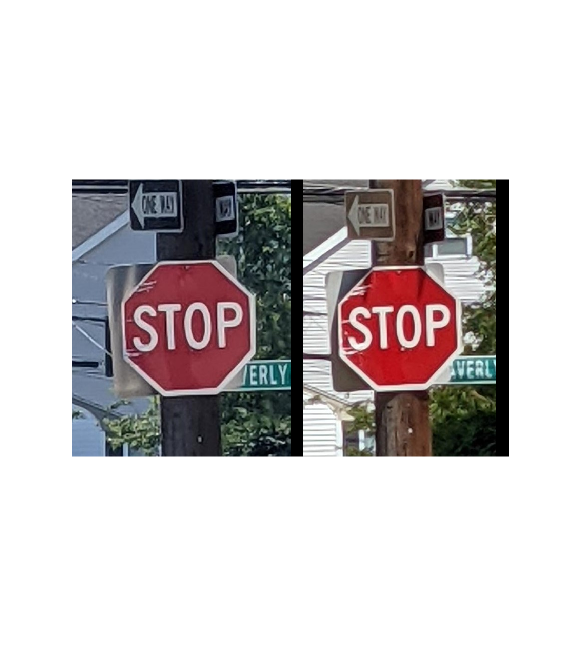

stop1RGB = imread("stop1.jpg");
stop2RGB = imread("stop2.jpg");
montage({stop1RGB,stop2RGB})

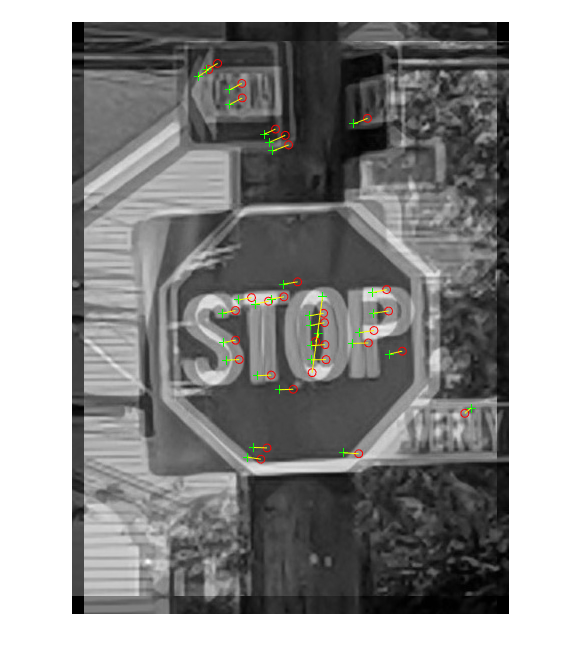

clf
stop1 = im2gray(stop1RGB);
stop2 = im2gray(stop2RGB);

pts1 = detectSURFFeatures(stop1);
pts2 = detectSURFFeatures(stop2);

[feat1,validPts1] = extractFeatures(stop1,pts1);
[feat2,validPts2] = extractFeatures(stop2,pts2);

indexPairs = matchFeatures(feat1,feat2,"MatchThreshold",20, ...
                                       "MaxRatio",0.6, ...
                                       "Metric",'SAD', ...
                                       "Unique",true);

matchedPoints1 = validPts1(indexPairs(:,1));
matchedPoints2 = validPts2(indexPairs(:,2));
showMatchedFeatures(stop1,stop2,matchedPoints1,matchedPoints2,"blend")

## Graded Quiz: Detecting, Extracting, and Matching Features

- Larger blobs are detected.

- It identifies the dominant orientation around the feature

- Based on the input object,

- Both

- By comparing the two feature descriptor vectors

- 757

- input: image & surfpoints. output: extracted feature descriptions and surfpoints

- [71 284]

img1 = imread("stop1.jpg");
img2 = imread("stop2.jpg");
img1 = im2gray(img1);
img2 = im2gray(img2);
pts1 = detectSURFFeatures(img1);
pts2 = detectSURFFeatures(img2);
length(feat2)

ans = 757

[feat1,validPts1] = extractFeatures(img1,pts1);
[feat2,validPts2] = extractFeatures(img2,pts2);
indexPairs = matchFeatures(feat1,feat2,"Unique",true);
indexPairs(15,:)

ans = 1×2 の uint32 行ベクトル
   141   498


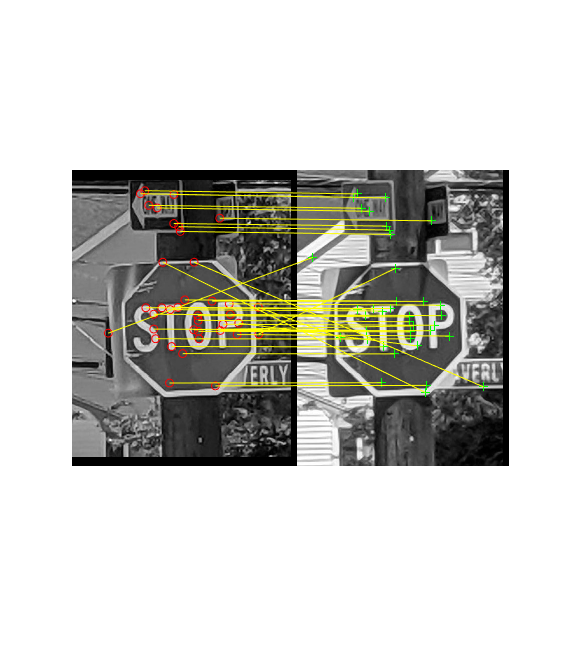

matchedPoints1 = validPts1(indexPairs(:,1));
matchedPoints2 = validPts2(indexPairs(:,2));
showMatchedFeatures(img1,img2,matchedPoints1,matchedPoints2,"montage")